# One Challenge for Digital Water: How to mine useful information from challenging sensor data

Cheng YANG

01/30/2020 - 02/05/2020

## Before Data Loading

The data loading script was saved in the ".\DataExtraction- dataDisplay.m" script. Detailed information was recoreded the file. 

The Input of for this live script was 'Raw2.mat'. 

## Data import and summary 

clear;
close all;
load('Raw2.mat');
Raw = Raw2 ;
clear Raw2;
full_range = unique(Raw.eachday_index2); % Collect the entire daterange 
comp_date =  unique(Raw{~isnan(Raw.Comp_Inf_BOD),'eachday_index2'}); % collect all composite date 
comp_date_missing =  full_range(~ismember(full_range,comp_date)); % collect missing composite date  
T_BOD= Raw(ismember(Raw.eachday_index2,comp_date),:); % Delete days with missing composite date 
clear Raw; 

### **Date information brief **

Datetime Range: 2016/5/5 to 2018/5/14  (intotal 689 days) where 51 days are missing (stored in comp_date_mssing). 

- Each weekday has a similar size of samples. Sun. 102; Mon. 100; Tue. 103; Wed. 101; Thu. 91; Fri. 89; Sat 102;

- Weekends together, there are 204 observation. After filtration, there are only 128 left. 

- Among those four filtering condition: 27 have at least a reading greater than 300 mg/L;  32 have at least a reading smaller than 50 mg/L; 31 have have leveled stages; and 18 have at least one missing values  

## Pattern Seperation 

### Preprocessing- reshaping and replace NaN with zeros  

        The collected sensor measurements were reshaped into one-day series with 720 points.  Each series starts from 6 am to 6 am of the next day, since composite samples are collected correspondingly. Missing values that existed in series were replaced with zeros to ensure algorithm implementation. 

% Extract data from dataframe into a matrix
xBOD = reshape(T_BOD.ZAPS_Inf_BOD,720,[])'; %  Predictors- sensor BOD- rows are one-day observations
xBOD(isnan(xBOD)) = 0;  % Replace NaN with zeros 
xflow = reshape(T_BOD.Inf_Flow,720,[])'; %  Predictors- sensor BOD- rows are one-day observations
yBOD = reshape(T_BOD.Comp_Inf_BOD,720,[])';
yBOD = nansum(yBOD,2); % Responses - composite BOD- rows are corresponding days 

% Load mannual label for good/dirty/junk labels 
df = readtable('Manual label data quality.csv','PreserveVariableNames',true);
% create label matrix for data 
labels_matrix = ~isnan(df.Dirty); % the first column is the dirty label 
labels_matrix = [labels_matrix  ~isnan(df.Junk)];  % the second column is the junk label 
labels_matrix = [labels_matrix  labels_matrix(:,2) | labels_matrix(:,1)];  % the third column is dirty or junk

save('xBOD','xBOD');
clear df;

How challenge the data look like:

Typical Profiles 

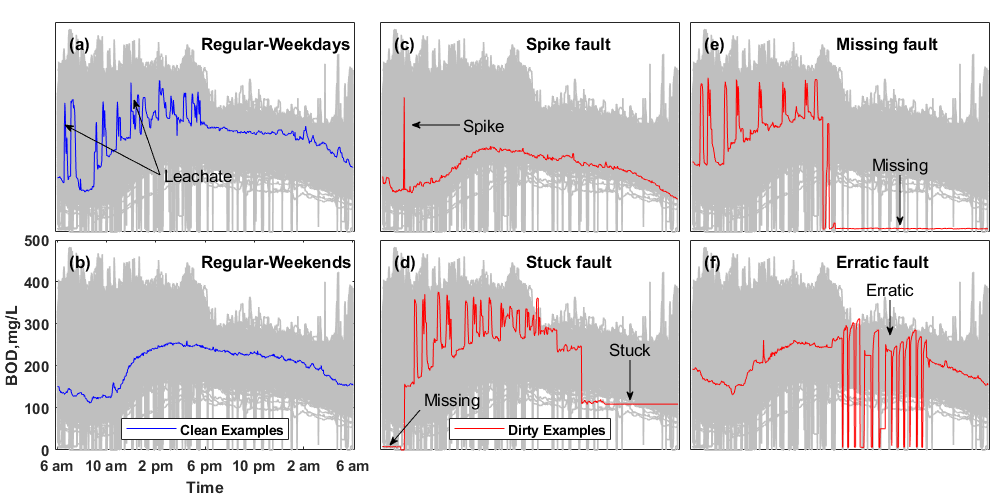

figure('position',[100 100 800 400],'Units','centimeters');
ax1 = axes('position',[0.055,0.535,0.30,0.42]); % Weekdays 
L1 = plot(xBOD(~labels_matrix(:,3),:)','color',[0.75 0.75 0.75],'LineWidth',1);
ylim([0,500]);
xlim([-5,725]);
set(gca,'YTick',[],'XTick',[]);
hold on;
plt1= plot(xBOD(27,:),'-b');
text(gca,30,450,'(a)',"FontWeight","bold");
text(gca,350,450,'Regular-Weekdays',"FontWeight","bold");

hold off;

ax2 = axes('position',[0.38,0.535,0.3,0.42]);  %spike 
L2 = plot(xBOD(~labels_matrix(:,3),:)','color',[0.75 0.75 0.75],'LineWidth',1);
ylim([0,500]);
xlim([-5,725]);
set(gca,'YTick',[],'XTick',[]);
hold on;
plot(xBOD(10,:),'-r');
text(gca,350,450,'Spike fault',"FontWeight","bold");
text(gca,30,450,'(c)',"FontWeight","bold");
hold off;

ax3 = axes('position',[0.69,0.535,0.3,0.42]); % Missing 
L3 = plot(xBOD(~labels_matrix(:,3),:)','color',[0.75 0.75 0.75],'LineWidth',1);
ylim([0,500]);
xlim([-5,725]);
set(gca,'YTick',[],'XTick',[]);
hold on;
plot(xBOD(50,:),'-r');
text(gca,350,450,'Missing fault',"FontWeight","bold");
text(gca,30,450,'(e)',"FontWeight","bold");
hold off;

ax4 = axes('position',[0.055,0.10,0.3,0.42]); % Weekend 
L4 = plot(xBOD(~labels_matrix(:,3),:)','color',[0.75 0.75 0.75],'LineWidth',1);
ylim([0,500]);
xlim([-5,725]);
set(gca,'XTick',linspace(0,720,7),'XTickLabel',{'6 am','10 am','2 pm','6 pm','10 pm','2 am','6 am'},...
    'FontWeight','bold');
xlabel('Time');
ylabel('BOD,mg/L');
hold on;
plot(xBOD(571,:),'-b');
text(gca,350,450,'Regular-Weekends',"FontWeight","bold");
text(gca,30,450,'(b)',"FontWeight","bold");
hold off;

ax5 = axes('position',[0.38,0.10,0.3,0.42]); % stuck 
L5 = plot(xBOD(~labels_matrix(:,3),:)','color',[0.75 0.75 0.75],'LineWidth',1);
ylim([0,500]);
xlim([-5,725]);
set(gca,'YTick',[],'XTick',[]);
hold on;
plt2= plot(xBOD(65,:),'-r');
text(gca,350,450,'Stuck fault',"FontWeight","bold");
text(gca,30,450,'(d)',"FontWeight","bold");

hold off;

ax6 = axes('position',[0.69,0.10,0.3,0.42]); % erratic 
L6 = plot(xBOD(~labels_matrix(:,3),:)','color',[0.75 0.75 0.75],'LineWidth',1);
ylim([0,500]);
xlim([-5,725]);
set(gca,'YTick',[],'XTick',[]);
hold on;
plot(xBOD(73,:),'-r');
text(gca,350,450,'Erratic fault',"FontWeight","bold");
text(gca,30,450,'(f)',"FontWeight","bold");
hold off;

legend(ax4,[plt1],'Clean Examples','location','south','FontWeight','bold');
legend(ax5,[plt2],'Dirty Examples','location','south','FontWeight','bold');
annotation('textarrow',[0.16 0.065],[0.65 0.75],'String','Leachate','HorizontalAlignment',"center",'HeadLength',5,"HeadWidth",5);
annotation('arrow',[0.16 0.134],[0.65 0.8],'HeadLength',5,"HeadWidth",5);
annotation('textarrow',[0.46 0.412],[0.75 0.75],'String','Spike','HorizontalAlignment',"center",'HeadLength',5,"HeadWidth",5);
annotation('textarrow',[0.9 0.9],[0.65 0.55],'String','Missing','HorizontalAlignment',"center",'HeadLength',5,"HeadWidth",5);
annotation('textarrow',[0.63 0.63],[0.28 0.2],'String','Stuck','HorizontalAlignment',"center",'HeadLength',5,"HeadWidth",5);

annotation('textarrow',[0.42 0.39],[0.18 0.11],'String','Missing','HorizontalAlignment',"center",'HeadLength',5,"HeadWidth",5);
annotation('textarrow',[0.89 0.89],[0.4 0.33],'String','Erratic','HorizontalAlignment',"center",'HeadLength',5,"HeadWidth",5);
% saveas(gcf,'.\\figures\\TypicalSignals.png');



### **Pattern Separation Alogrithm - From Ordinary Least Square to Regularized Least Squares **

#### **Oridnary Least Squares **

An one-day series could be approximated as the sum of diurnal pattern and residuals, as $y=\Gamma x+\epsilon \;$, where the $\Gamma x\;$is the diurnal pattern, and $\epsilon$ is the residuals. The formula could be further reduced into the matrix form as 


$$y=\Gamma x\;+\;\epsilon$$
 

In the ordinary least squares, the objective is to mimimize the difference between $y$ and $\Gamma x\;$, therefore, the loss function could be written as 


$$\hat{x} =\;\underset{x}{\arg \;\min } \;\left\|y-\Gamma x\right\|{\;}_2^{2\;} \;\;$$


The diurnal term was approximated as the 3rd-order Fourier series,  $y_i =x_1 +\sum_{k=1}^3 x_{2i\;} \cos \left(k\cdot w\cdot \;i\right)+\sum_{k=1}^3 x_{2\;i+1\;} \sin \left(k\cdot w\cdot \;i\right)\;+\epsilon_i$, while in matrix form as 

$\begin{array}{l}
\left\lbrack \begin{array}{c}
y_1 \\
\vdots \\
y_i \\
\vdots \\
y_{720} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccccccc}
1 & \cos \left(1\cdot w\cdot 1\right) & \sin \left(1\cdot w\cdot 1\right) & \cos \left(2\cdot w\cdot 1\right) & \sin \left(2\cdot w\cdot 1\right) & \cos \left(3\cdot w\cdot 1\right) & \sin \left(3\cdot w\cdot 1\right)\\
\vdots  & \vdots  & \vdots  & \vdots  & \vdots  & \vdots  & \vdots \\
1 & \cos \left(1\cdot w\cdot i\right) & \sin \left(1\cdot w\cdot i\right) & \cos \left(2\cdot w\cdot i\right) & \sin \left(2\cdot w\cdot i\right) & \cos \left(3\cdot w\cdot i\right) & \sin \left(3\cdot w\cdot i\right)\\
\vdots  & \vdots  & \vdots  & \vdots  & \vdots  & \vdots  & \vdots \\
1 & \cos \left(1\cdot w\cdot 720\right) & \sin \left(1\cdot w\cdot 720\right) & \cos \left(2\cdot w\cdot 720\right) & \sin \left(2\cdot w\cdot 720\right) & \sin \left(3\cdot w\cdot 720\right) & \sin \left(3\cdot w\cdot 720\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 \\
x_4 \\
x_5 \\
x_6 \\
x_7 
\end{array}\right\rbrack \\
\;
\end{array}$ + $\left\lbrack \begin{array}{c}
\epsilon_1 \\
\vdots \\
\epsilon_i \\
\vdots \\
\epsilon_{720} 
\end{array}\right\rbrack \Rightarrow y=\Gamma x+\epsilon$ 


$$\;$$


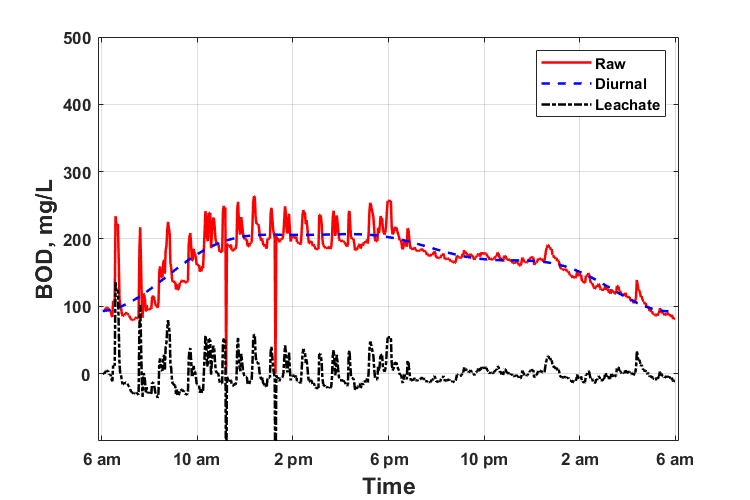

% Choose EXAMPLE idX
idx = 1;
% Set-up global constants  
d = 3;
ols_y = xBOD(idx,:)';
t = 1:length(ols_y);
w= 2*pi/720;
ols_y = xBOD(idx,:)';
ols_x = zeros(length(ols_y),2*d+1);
for  i = 1:d   
    ols_x(:,2*i) = cos(i*w*t);   
    ols_x(:,2*i+1) = sin(i*w*t);
end
ols_x(:,1) = ones(length(ols_y),1);
ols_beta = ols_x \ ols_y;

figure('position',[0 0 600 400],'Units','centimeters');
ax1 = singleTSplot(ols_y);
hold on;
ax2 = plot(ols_x*ols_beta);
ax3 = plot(ols_y - ols_x*ols_beta);

set(ax1,'color','red','LineWidth',1.5);
set(ax2,'color','blue','LineWidth',1.5,'LineStyle','--');
set(ax3,'color','black','LineWidth',1.5,'LineStyle','-.');


hold off;
legend('Raw','Diurnal','Leachate');   

#### Result and Discussion of Ordinary Least Squares 

As we can see in the figures above. When the leachate(spikes) exists, the diurnal patterns were highly skewed by the leachate. Meanwhile, the residuals are not fully representative for leachate, since by nature, the leachate is unlikely to be large negative values by nature. Therefore, OLS is not appicable for seperating the leachate component. 

### **Regularized Least Squares - Ridge Regularization**

        If we want to further seperate the leachate component in the sensor signals, then an one-day series could be approximated as the sum of diurnal pattern, leachate and residuals, as $y=\Gamma x+s+\epsilon \;$, where the $\Gamma x\;$is the diurnal pattern, the $s$ is the leachate pattern and $\epsilon$ is the residuals. The formula could be further reduced into the matrix form as 


$$y=\Gamma x+\textrm{Is}+\epsilon =\left\lbrack \begin{array}{cc}
\Gamma \; & I
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
s
\end{array}\right\rbrack +\epsilon =\tilde{A} \;\tilde{x} +\epsilon$$
 

Where $I$ is the Identity matrix, and $\tilde{A} \;$is the horizontal concatenation of $\Gamma$ and $I$, and $\tilde{x}$ is the vertical concatenation of $x$ and $s$. Simliarly, this problem has been transfromed  into 

$\hat{x} =\;\underset{x}{\arg \;\min } \;\left\|y-\Gamma x-s\right\|{\;}_2^{2\;} =\underset{\tilde{x} }{\arg \;\min } \;\left\|y-\tilde{A} \tilde{x} \right\|{\;}_2^2 \;$. 

Since the system $y=\tilde{A} \tilde{x} +\epsilon$  is always an under-determined system (equations are smaller than unknowns). Usually Ridge/Lasso - regression is used. In the Ridge-regularized least squares, the objective is to mimimize the difference between $y$ and $\Gamma x+s\;$, therefore, the problem could be written as 

$\hat{x} =\underset{\tilde{x} }{\arg \;\min } \;\left\|y-\tilde{A} \tilde{x} \right\|{\;}_2^2 \;+\lambda \;\left\|\tilde{x} \right\|{\;}_2^2 \;$ . 

Regularization term ( $\lambda \left\|\tilde{x} \right\|{\;}_2^2$ ) ensures the under-determined system transforming into an over-determined system and finally guranteees a unique solution. Meanwhile, it forces every elements in $\tilde{x}$ to be as close to each other as possible.   

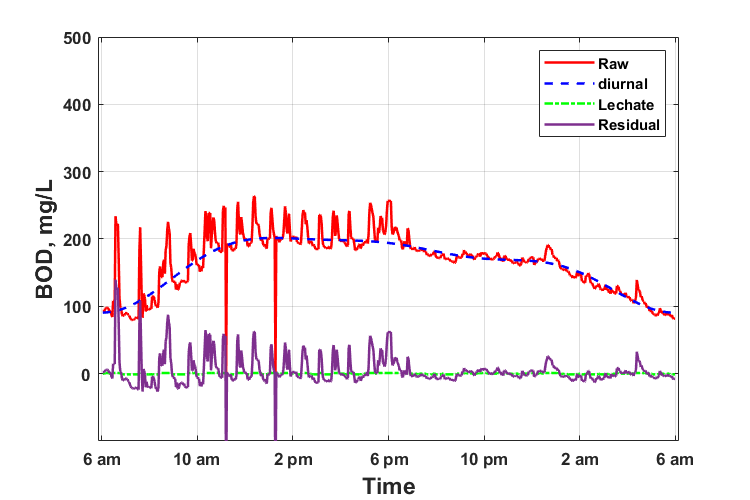

% Prepare for RRLS  
rrls_x = zeros(length(ols_y),2*d);
for  i = 1:d   
    rrls_x(:,2*i-1) = cos(i*w*t);   
    rrls_x(:,2*i) = sin(i*w*t);
end
Atil = [rrls_x eye(720,720)];

% ols_fiiting with fitrlinear 
Mdl = fitrlinear(Atil,ols_y);
rrls_dirunal = rrls_x*Mdl.Beta(1:6) + Mdl.Bias;  

% plotting the results 
figure('position',[0 0 600 400],'Units','centimeters');
ax1 = singleTSplot(ols_y);
hold on;
ax2 = plot(rrls_dirunal);
ax3 = plot(Mdl.Beta(7:end));
ax4 = plot(ols_y-rrls_dirunal-Mdl.Beta(7:end));
set(ax1,'color','red','LineWidth',1.5);
set(ax2,'color','blue','LineWidth',1.5,'LineStyle','--');
set(ax3,'color','green','LineWidth',1.5,'LineStyle','-.');
set(ax4,'LineWidth',1.5);

hold off;
legend('Raw','diurnal','Lechate','Residual');  

#### Result and Discussion of Ridge Regression

The seperation results are showed in Figure above. Unlike what we expected, the leachate component was not incoprated into the $s$ part, instead, it goes into the residual terms. Besides, the skewness issued was not fully solved by the RLS. Even if we thought the residual term was leachate, large negative values still exists, which is again not correct by nature.   

### **Regularized Least Squares - Shifted Huber-Hinge Regularization( Non-negtaive Regularization)**

Agian, an one-day series could be approximated as the sum of diurnal pattern, leachate and residuals, as $y=\Gamma x+s+\epsilon \;$, where the $\Gamma x\;$is the diurnal pattern, the $s$ is the leachate pattern and $\epsilon$ is the residuals. The formula could be further reduced into the matrix form as 


$$y=\Gamma x+\textrm{Is}+\epsilon =\left\lbrack \begin{array}{cc}
\Gamma \; & I
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
s
\end{array}\right\rbrack +\epsilon =\tilde{A} \;\tilde{x} +\epsilon$$
 

Where $I$ is the Identity matrix, and $\tilde{A} \;$is the horizontal concatenation of $\Gamma$ and $I$, and $\tilde{x}$ is the vertical concatenation of $x$ and $s$. Simliarly, this problem has been transfromed  into 

$\hat{x} =\;\underset{x}{\arg \;\min } \;\left\|y-\Gamma x-s\right\|{\;}_2^{2\;} =\underset{\tilde{x} }{\arg \;\min } \;\left\|y-\tilde{A} \tilde{x} \right\|{\;}_2^2 \;$. 

This time, regularization was changed and was applied on the leachate term, $s$,  as 


$$\hat{x} =\;\underset{x}{\arg \;\min } \;{\left\|y-\Gamma x-s\;\right\|}_2^2 \;+\lambda \cdot h\left(s\right)\;$$


The lechate pattern is regularized by the shifted huber-hinger error function$\;h\left(x\right)$, which penalizes the negative part. The shifted huber-hinger error function is: $h\left(x\right)=\left\lbrace \begin{array}{cc}
-x-\frac{\;\delta }{2} & x\le -\delta \\
\;\;\frac{1}{2\delta }x^2  & -\delta <x\le 0\;\\
0 & x>0
\end{array}\right.\;$ and its derivative is:   $\frac{\mathrm{d}}{\mathrm{d}x}h\left(x\right)=\left\lbrace \begin{array}{cc}
-1 & x\le -\delta \\
\;\;\frac{1}{\delta }x & -\delta <x\le 0\;\\
0 & x>0
\end{array}\;\right.$  .The shape of these two functions are displayed below. 

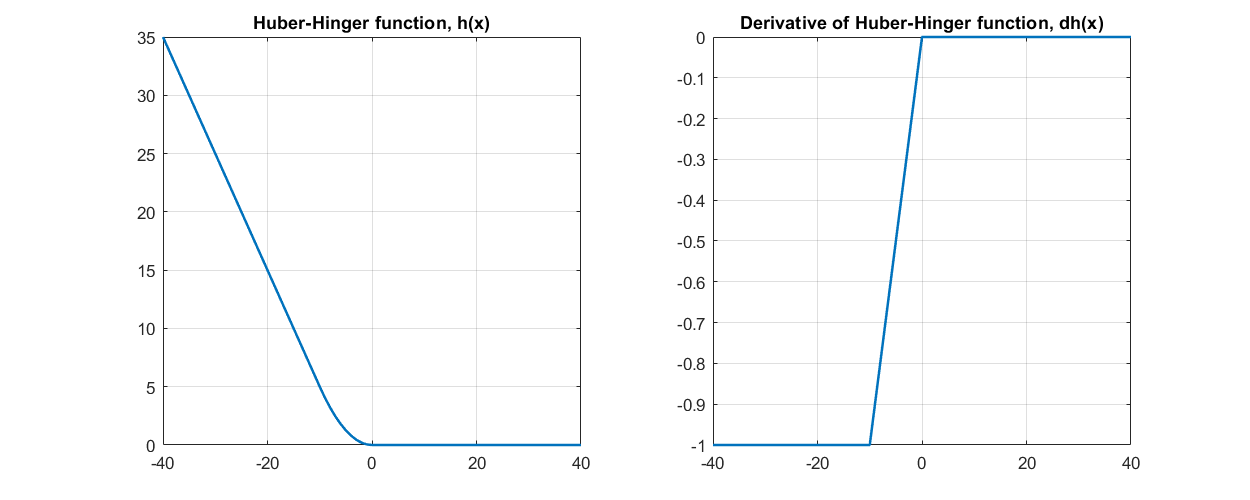

% plotting the results 
figure('position',[0 0 1000 400],'Units','centimeters');
subplot(1,2,1);
plot(-40:40,hubhin2(-40:40,10),'-','LineWidth',1.5);
grid on;
title('Huber-Hinger function, h(x)')
subplot(1,2,2);
plot(-40:40,dhubhin2(-40:40,10),'-','LineWidth',1.5);

grid on;
title('Derivative of Huber-Hinger function, dh(x)')

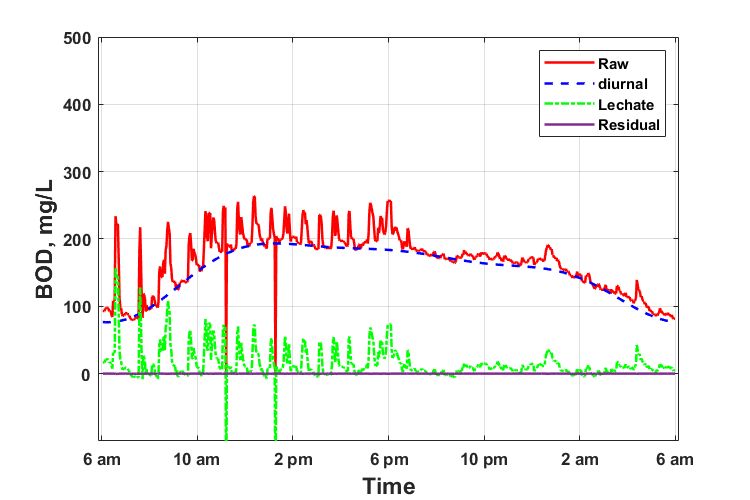

% The calculation of pattern seperation is in 'seperatePatternScript.m', 
% the seperated results were stored 'xDiurnal.mat' and 'xResidual.mat' .
load xDiurnal.mat;
load xLeachate.mat;

% plotting the results of RLS
figure('position',[0 0 600 400],'Units','centimeters');
ax1 = singleTSplot(ols_y);
hold on;
ax2 = plot(xDiurnal(idx,:));
ax3 = plot(xLeachate(idx,:));
xResidual = xBOD - xDiurnal - xLeachate;
ax4 = plot(xResidual(idx,:));
set(ax1,'color','red','LineWidth',1.5);
set(ax2,'color','blue','LineWidth',1.5,'LineStyle','--');
set(ax3,'color','green','LineWidth',1.5,'LineStyle','-.');
set(ax4,'LineWidth',1.5);

hold off;
legend('Raw','diurnal','Lechate','Residual');

#### Result and Discussion of Shifted Huber-Hinger Regularization 

The seperation results are showed in Figure above.The seperation results are quite satisfactory. Leachate was separated in the s and most of them are non-negative. The magnitude of residuals are around 0.5 mg/L.   

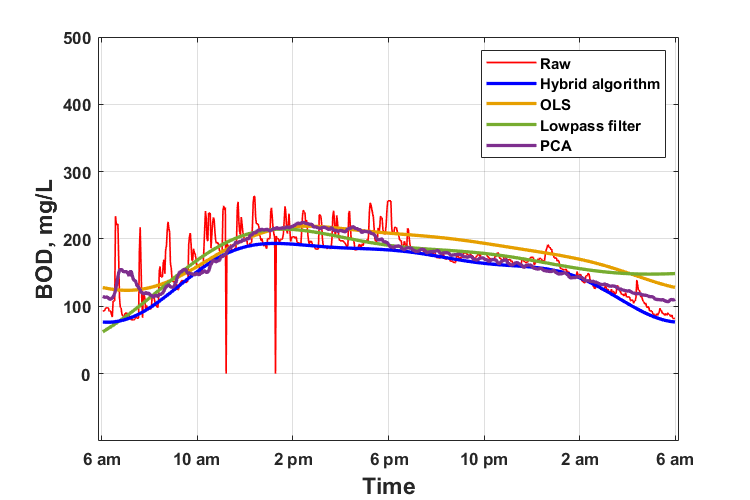

% Compare the result of above three methods 
figure('position',[0 0 600 400],'Units','points');
ax1 = singleTSplot(ols_y);
hold on;
ax2 = plot(ols_dirunal);
% design a lowpass filter for it
filter= designfilt('lowpassiir','PassbandFrequency',2.5,...
    'StopbandFrequency',2.7,'PassbandRipple',0.05,...
    'StopbandAttenuation',60,'SampleRate',720,'DesignMethod','ellip');
filter_y = filtfilt(filter,xBOD(idx,:));
ax3 = plot(filter_y);
ax4 = plot(xDiurnal(idx,:));

%% PCA 
[U,S,V] = svd(xBOD,'econ');
S(5:end,5:end) =0;
xBOD_approx = U*S*V';
ax5 = plot(xBOD_approx(idx,:));

set(ax1,'color','red','LineWidth',1);
set(ax2,'color',[230 159 0 10]/255,'LineWidth',2,'LineStyle','-');
set(ax3,'color',[0.4660 0.6740 0.1880],'LineWidth',2,'LineStyle','-');
set(ax4,'color','blue','LineWidth',2,'LineStyle','-');
set(ax5,'color',[0.4940 0.1840 0.5560],'LineWidth',2,'LineStyle','-');
legend([ax1 ax4 ax2 ax3 ax5],'Raw','Hybrid algorithm','OLS','Lowpass filter', 'PCA');



% X&Y ticks
ylim([-100,500]);
xlim([-5,725]);
set(gca,'XTick',linspace(0,720,7),'XTickLabel',{'6 am','10 am','2 pm','6 pm','10 pm','2 am','6 am'},...
    'FontWeight','bold');
set(gca,'YTick',linspace(0,500,6));

% X & Y labels
xlabel('Time','FontSize',14,'FontWeight','bold');
ylabel('BOD, mg/L','FontSize',14,'FontWeight','bold');

grid on;
hold off;



% clear workspace 
% clearvars -except comp_date_missing comp_date full_range xBOD xResidual xDiurnal xLeachate yBOD xflow T_BOD labels_matrix ;

## Quality Classification 

### Similarity Analysis

A generally acknowledged fact is that for sewage system the diurnal loading variation should not be so different. (References to be filled in). Therefore, the seperated diurnal patterns should be similar to each other, because the leachate patterns, whose irregular occurance cause trouble to the similarity, were rid of. In other words, any diurnal patterns with low similarity with others tend to result from sensor issues. Various similarity measures are applicable to compare two patterns(Ref.Sung-Hyuk Cha), and herein the Pearson correlation coefficient was use as below. The value range of $\rho$ is -1 to 1. The closer $\rho \;$is to 1, the more simlar two diurnal patterns are.  


$$\rho \;\left(x_i ,x_j \right)=\frac{\sum_{k=1}^{720} \left(x_{i,k} -\bar{x_i } \right)\left(x_{j,k} -\bar{x_j } \right)\;}{\sqrt{\sum_{k=1}^{720} {\left(x_{i,k} -\bar{x_i } \right)}^2 \;\cdot \;\sum_{k=1}^{720} {\left(x_{j,k} -\bar{x_j } \right)}^2 \;}}$$
 

Considering the fact that a problematic profile would be highly similar to another problematic one, a simple decision rule basd on  correlations statistics(min/max/median/mean) are not robust.(See figure below). Therefore, the similarity distribution was used as an alternative. Correlations of one day are histogrammed into  10 bins  with a bin width of 0.2. Similarity distribution results could be seen in both figures below and two gif documents, 'clean.gif' & 'dirty.gif'. 

% Calculate the correlation of diurnal patterns 
correlation_diurnal_raw = corr(xDiurnal');
correlation_diurnal_raw(1:(size(xDiurnal,1)+1):end) = NaN; % set diagnoal elements into NaN, for calculation need

% calculate similarity distribution
binEdges= -1:0.2:1;
similarity_distribution_raw = nan(size(correlation_diurnal_raw,1),length(binEdges)-1);
for i = 1:size(similarity_distribution_raw,1)
    [similarity_distribution_raw(i,:), ~]=histcounts(correlation_diurnal_raw(i,:),binEdges,'Normalization','probability');
end

% calculate the simple statistics of similarity 
% 1- mean 2- min 3- first quantile 4- Median 5-Third quantile 6 - Maximum 
correlation_statistics_diurnal_raw = nan(size(correlation_diurnal_raw,1),6);
for i= 1:size(correlation_diurnal_raw,1)
    x = correlation_diurnal_raw(:,i);
    x = x(~isnan(x));
    correlation_statistics_diurnal_raw(i,:)  = [mean(x) min(x) quantile(x,[0.25 0.50 0.75]) max(x)];
end

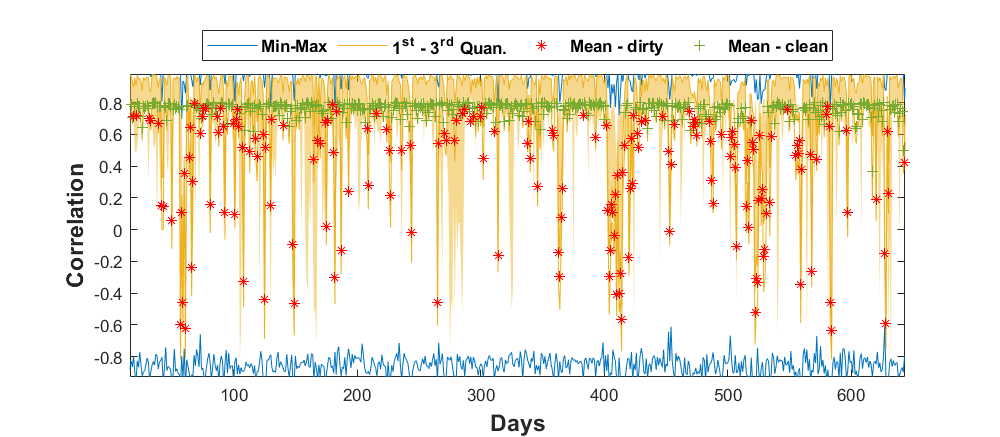

% Figure to show simple statistics won't work 
figure('position',[0 0 800 350],'Units','centimeters');

ax1= plot(correlation_statistics_diurnal_raw(:,2),'-',"Color",[0 0.4470 0.7410]);
hold on;
ax2= plot(correlation_statistics_diurnal_raw(:,6),'-',"Color",[0 0.4470 0.7410]);
fill([1:688 fliplr(1:688)]',[correlation_statistics_diurnal_raw(:,5); fliplr(correlation_statistics_diurnal_raw(:,3))],...
    [0.9290 0.6940 0.1250],'FaceAlpha',0.5,'EdgeColor',"none");
ax3= plot(correlation_statistics_diurnal_raw(:,3),'-',"Color",[0.9290 0.6940 0.1250]);
ax4= plot(correlation_statistics_diurnal_raw(:,5),'-',"Color",[0.9290 0.6940 0.1250]);
temp = 1:688;
ax6= plot(temp(~labels_matrix(:,3)),correlation_statistics_diurnal_raw(~labels_matrix(:,3),1),'+','Color',[0.4660 0.6740 0.1880]);
ax5= plot(temp(labels_matrix(:,3)),correlation_statistics_diurnal_raw(labels_matrix(:,3),1),'*r');

xlim([-1,689]);
ylim([-1,1.1]);
xlabel('Days','FontSize',14,'FontWeight','bold');
ylabel('Correlation','FontSize',14,'FontWeight','bold');
hleglines = [ax1 ax3 ax5 ax6];
legend(hleglines,'Min-Max','1^s^t - 3^r^d Quan.','Mean - dirty','Mean - clean',...

    'FontSize',10,'FontWeight','bold','Location','northoutside','NumColumns',4);
clear ax1 ax2 ax3 ax4 ax5 ax6 i binEdges temp x hleglines;

%classification_set_quan = [correlation_statistics_diurnal_raw(:,[3 5]) classification_set0(:,end)];

% Extract ID of clean and dirty day extraction. 
idx= 1:size(xBOD,1);
clean_id = idx(~labels_matrix(:,3));
dirty_id = idx(labels_matrix(:,3));

Typical Clean and Dirty figures has been plotted in via script 'FigureOutputs.m'. All pictures are stored in the subfile- 'figures - clean/dirty'. 

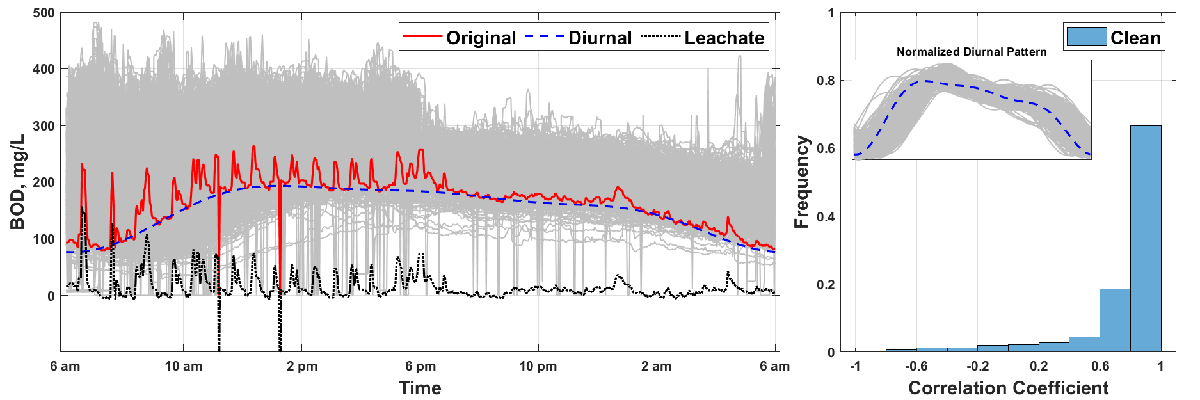

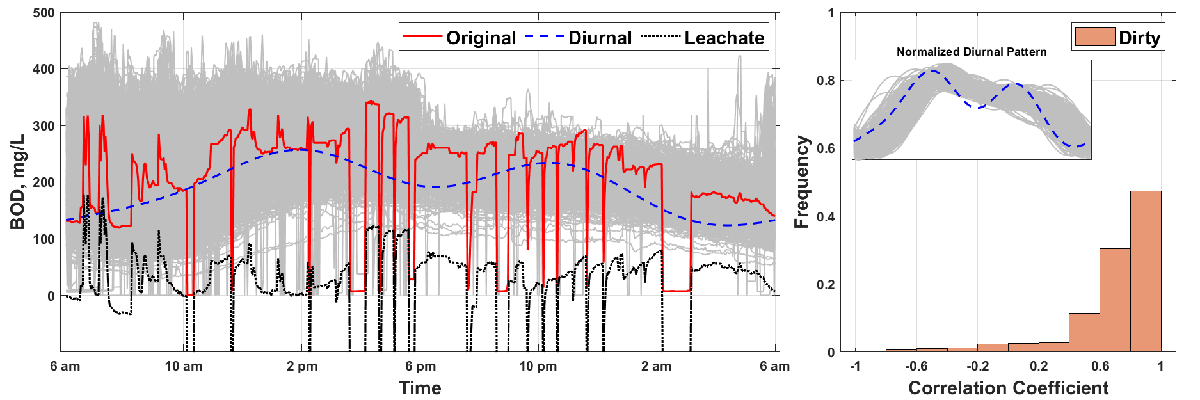

By closely observing the difference of similarity distribution between clean and dirty series, we found out that occassionally, sensor will get stuck and coincidentaly, the stuck part would not affect the distribution so much that the exponential-like shape was perserved(as showed above). Frequencies of 11 bins alone are not enough full 

In order to improve this situation, additional variable, called Stuck Index (SI) was introduce. It measures the fraction of how many measurements are not changed from its previous measurement. 


$$\textrm{SI}=\frac{\sum_{t=1}^n y\left(t\right)-y\left(t+1\right)}{n-1\;}$$
    

Finally, the frequencies of each bins, as well as the stuck index, were used as predictors for classification. The classification is implemented by Matlab Classification Learner. 

%Calcualte the stuck index 
stuck_idx = sum(diff(xBOD') == 0)/719;


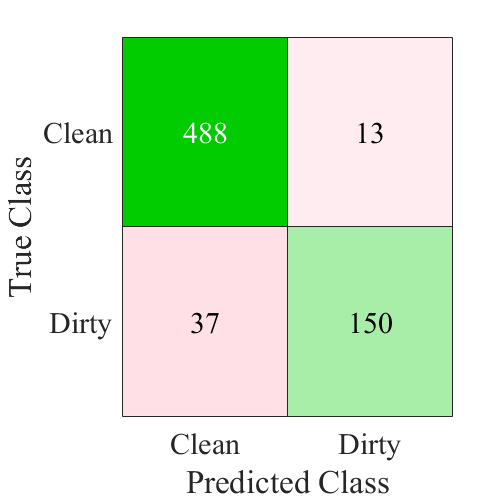

% Train logistic Regression model without SI
rng(01);
warning('off');
classification_set0 = [similarity_distribution_raw  ~labels_matrix(:,3)]; 
[LogRegMdl,ValAcuracy]=trainClassifier0(classification_set0);
Classification_pred = LogRegMdl.predictFcn(classification_set0(:,1:end-1));
warning('on'); 

% Extract the classification result in 
TP =[];
TN =[];
FP =[];
FN_rid_by_second =[];
for i =1:length(Classification_pred)
    if (Classification_pred(i) == 0) && (~labels_matrix(i,3) == 0)      % True positive
        TP = [TP;i];
    elseif (Classification_pred(i) == 1) && (~labels_matrix(i,3) == 0)      % False negative
        FN_rid_by_second= [FN_rid_by_second;i];
    elseif Classification_pred(i) == 1 && (~labels_matrix(i,3) == 1)      % True negative
        TN= [TN;i];
    else %Classification_pred(i) == 0 & (labels_matrix(:,3) == 1)      % False positive
        FP= [FP;i];
    end
    
end
% plot results
[X,Y] = meshgrid(1:2,1:2);
Confusion_Matrix = [ length(TP)/(length(TP)+length(FP))  length(FN_rid_by_second)/(length(FN_rid_by_second)+length(TN)) ;
                     length(FP)/(length(TP)+length(FP))  length(TN)/(length(FN_rid_by_second)+length(TN)) ];
figure('position',[0 0 400 400],'Units','centimeters');
true_label = cell(length(Classification_pred),1);
true_label(:) = {'Clean'};
true_label(labels_matrix(:,3)) = {'Dirty'} ;

pred_label = cell(length(Classification_pred),1);
pred_label(:) = {'Clean'};
pred_label(Classification_pred == 0) = {'Dirty'} ;

cm= confusionchart(true_label,pred_label);%,"Normalization","total-normalized"); %,'RowSummary',"row-normalized","ColumnSummary","column-normalized");
cm.DiagonalColor    = 	[0 0.8 0];
cm.OffDiagonalColor =   [1 0 0.2];
cm.FontSize = 18;
cm.FontName = 'Times New Roman';

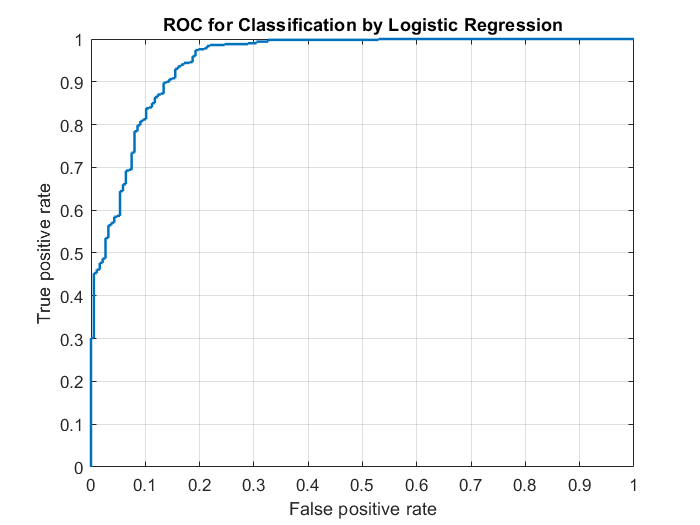

figure;
scores = LogRegMdl.GeneralizedLinearModel.Fitted.Probability;
[X,Y,T,AUC] = perfcurve(true_label,scores,'Clean');
plot(X,Y,'lineWidth',1.5);
xlabel('False positive rate') ;
ylabel('True positive rate');
title('ROC for Classification by Logistic Regression');
grid on;


[SUCCESS,MESSAGE,MESSAGEID] = mkdir('.\figures\1st classification\False Negative');
for j = 1:length(FN_rid_by_second)
        [status,message,messageId] = copyfile(['.\figures\dirty\' num2str(FN_rid_by_second(j)) '.png'],'.\figures\1st classification\False Negative');
end

[SUCCESS,MESSAGE,MESSAGEID] = mkdir('.\figures\1st classification\False Positive');
for j = 1:length(FP)
        [status,message,messageId] = copyfile(['.\figures\clean\' num2str(FP(j)) '.png'],'.\figures\1st classification\False Positive');
end

FN0 = FN_rid_by_second;
FP0 = FP;


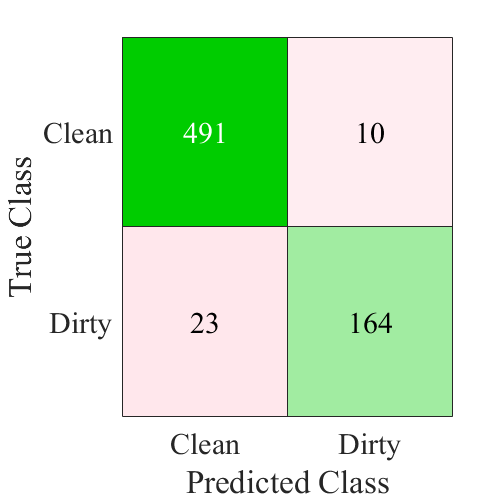

% Train logistic Regression model with SI 
classification_set = [similarity_distribution_raw stuck_idx' ~labels_matrix(:,3)]; 
rng(0408);
warning('off');
[LogRegMdl,ValAcuracy]=trainClassifier(classification_set);
Classification_pred = LogRegMdl.predictFcn(classification_set(:,1:end-1));
warning('on'); 

% Extract the classification result in 
TP =[];
TN =[];
FP =[];
FN =[];
for i =1:length(Classification_pred)
    if (Classification_pred(i) == 0) && (~labels_matrix(i,3) == 0)      % True positive
        TP = [TP;i];
    elseif (Classification_pred(i) == 1) && (~labels_matrix(i,3) == 0)      % False negative
        FN_rid_by_second= [FN_rid_by_second;i];
    elseif Classification_pred(i) == 1 && (~labels_matrix(i,3) == 1)      % True negative
        TN= [TN;i];
    else %Classification_pred(i) == 0 & (labels_matrix(:,3) == 1)      % False positive
        FP= [FP;i];
    end
    
end
% plot results
[X,Y] = meshgrid(1:2,1:2);
Confusion_Matrix = [ length(TP)/(length(TP)+length(FP))  length(FN_rid_by_second)/(length(FN_rid_by_second)+length(TN)) ;
                     length(FP)/(length(TP)+length(FP))  length(TN)/(length(FN_rid_by_second)+length(TN)) ];
figure('position',[0 0 400 400],'Units','centimeters');
true_label = cell(length(Classification_pred),1);
true_label(:) = {'Clean'};
true_label(labels_matrix(:,3)) = {'Dirty'} ;

pred_label = cell(length(Classification_pred),1);
pred_label(:) = {'Clean'};
pred_label(Classification_pred == 0) = {'Dirty'} ;

cm= confusionchart(true_label,pred_label);%,"Normalization","total-normalized"); %,'RowSummary',"row-normalized","ColumnSummary","column-normalized");
cm.DiagonalColor    = 	[0 0.8 0];
cm.OffDiagonalColor =   [1 0 0.2];
cm.FontSize = 18;
cm.FontName = 'Times New Roman';

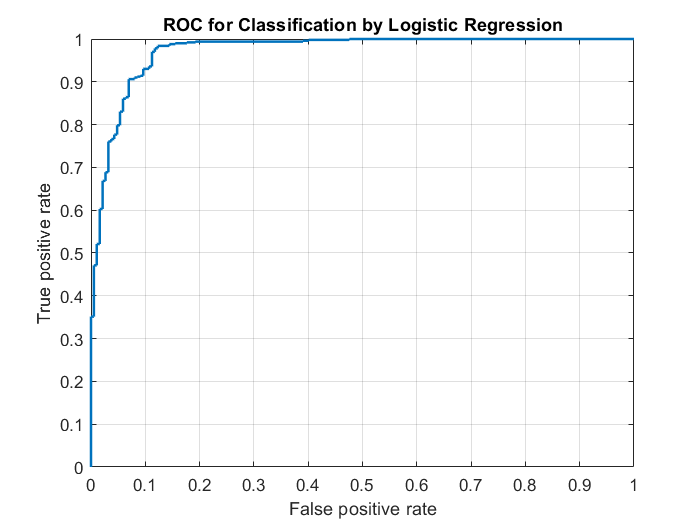

figure;
scores = LogRegMdl.GeneralizedLinearModel.Fitted.Probability;
[X,Y,T,AUC] = perfcurve(true_label,scores,'Clean');
plot(X,Y,'lineWidth',1.5);
xlabel('False positive rate') ;
ylabel('True positive rate');
title('ROC for Classification by Logistic Regression');
grid on;

[SUCCESS,MESSAGE,MESSAGEID] = mkdir('.\figures\2nd classification\False Negative');
for j = 1:length(FN_rid_by_second)
        [status,message,messageId] = copyfile(['.\figures\dirty\' num2str(FN_rid_by_second(j)) '.png'],'.\figures\2nd classification\False Negative');
end

[SUCCESS,MESSAGE,MESSAGEID] = mkdir('.\figures\2nd classification\False Positive');
for j = 1:length(FP)
        [status,message,messageId] = copyfile(['.\figures\clean\' num2str(FP(j)) '.png'],'.\figures\2nd classification\False Positive');
end

FN_rid_by_second_classification = FN0(~ismember(FN0,FN));
[SUCCESS,MESSAGE,MESSAGEID] = mkdir('.\figures\2nd classification\FN_rid_by_second_classification');
for j = 1:length(FN_rid_by_second_classification)
        [status,message,messageId] = copyfile(['.\figures\dirty\' num2str(FN_rid_by_second_classification(j)) '.png'],'.\figures\2nd classification\FN_rid_by_second_classification');
end

Acutally, we are more concerned about dirty data that have been reported as 'Clean' (Left bottom), since false-dirty data will not change if go through the therapy. Meanwhile, if we carefully examine the erroreous classification, it turns out that some profiles should be labeled the opposite but while during manual work, we didn't labeled correctly, such as below: 

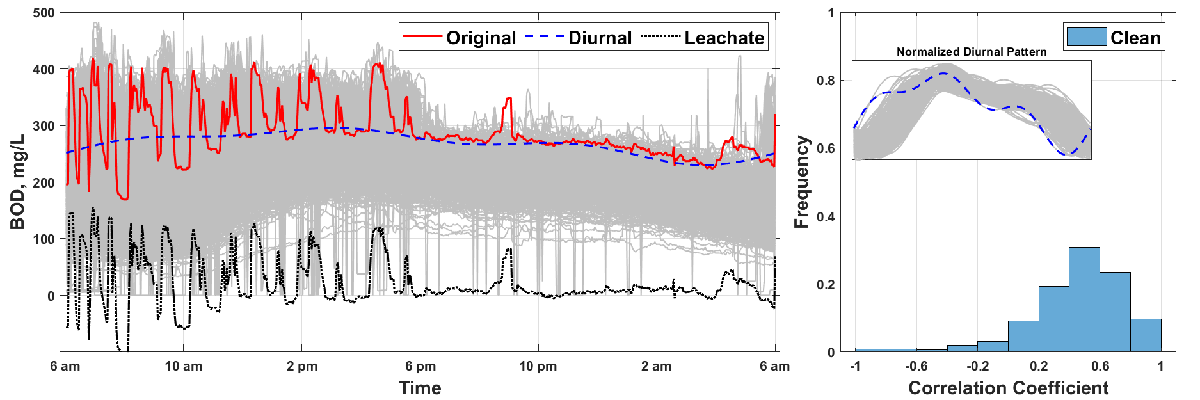

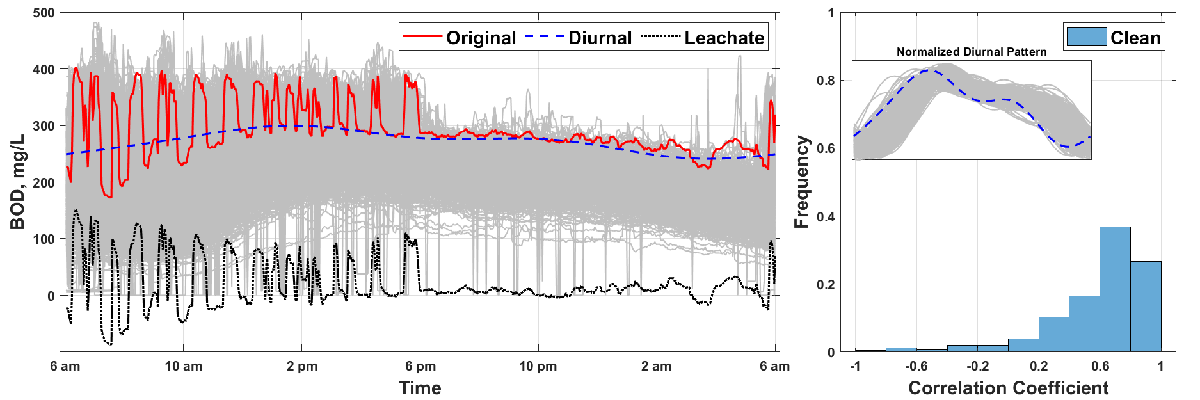

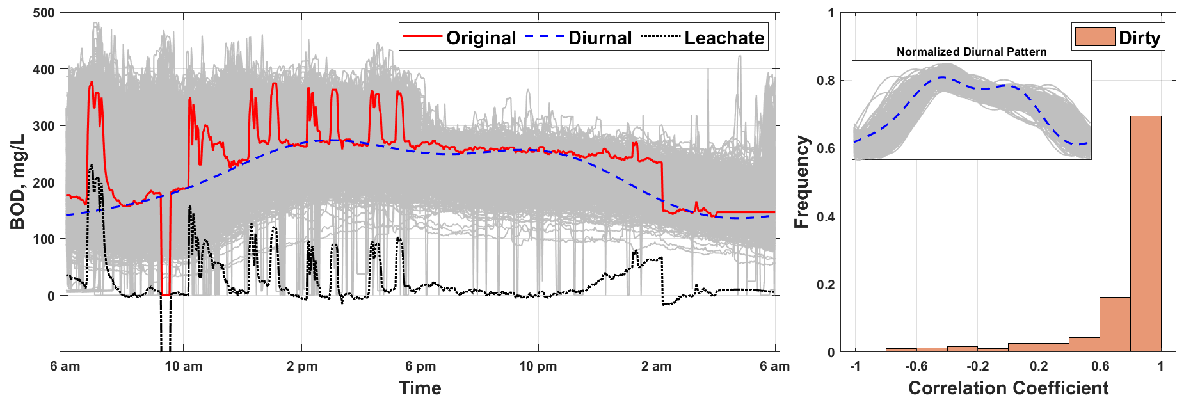

## Data Validation 

### Mapping from sensor data to composite data 

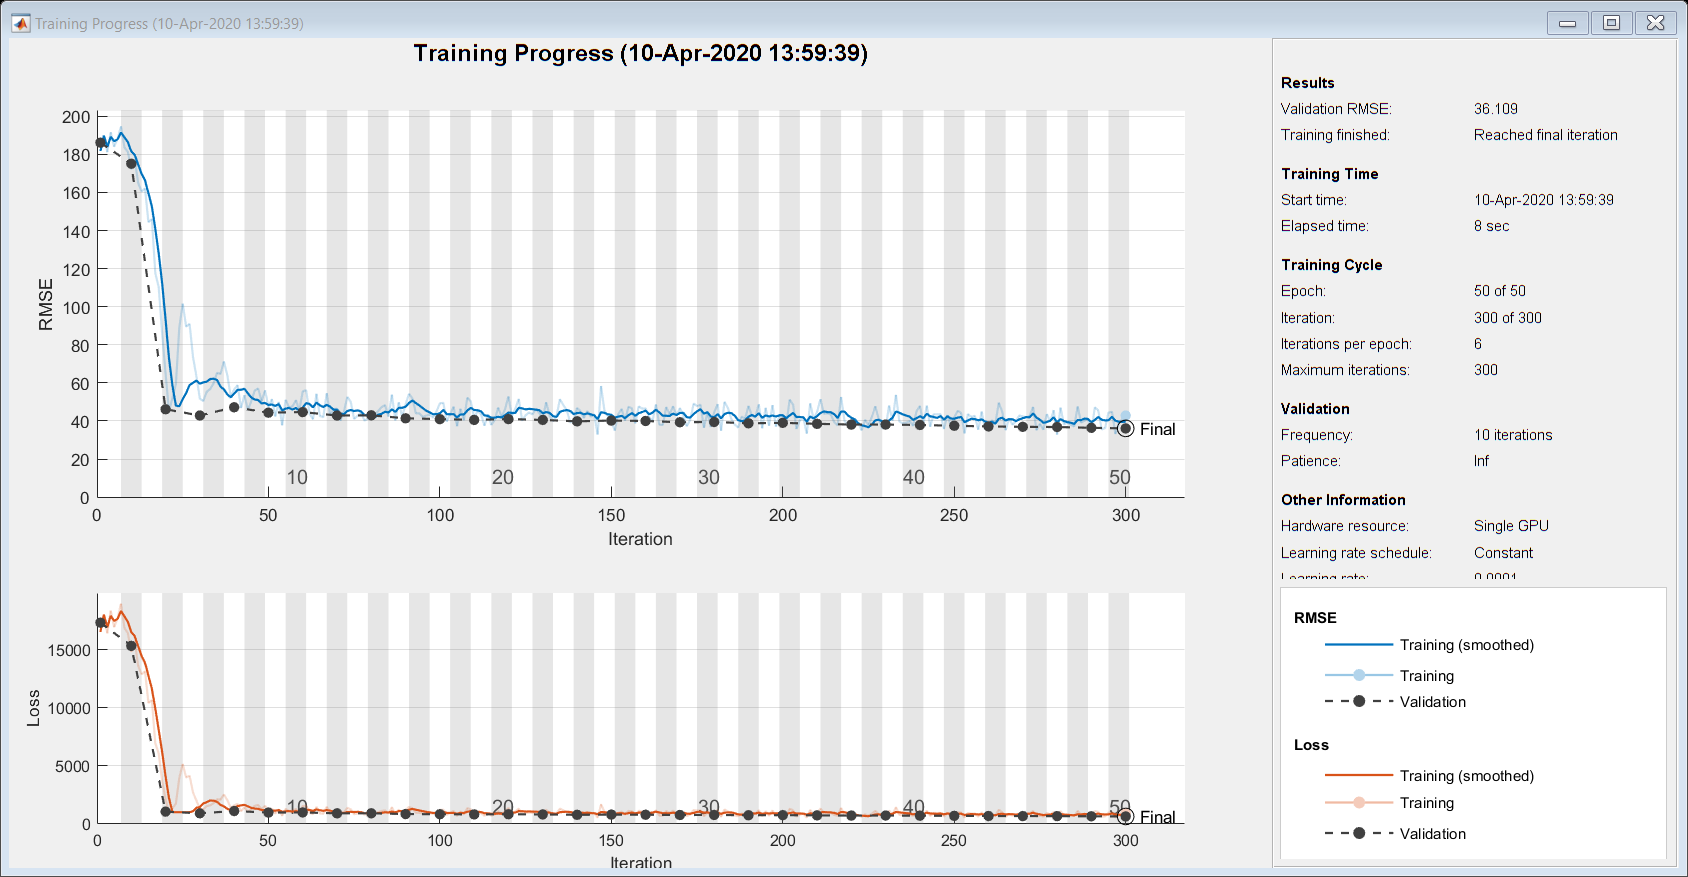

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |       181.82 |       186.17 |   16529.9199 |   17329.1270 |      1.0000e-04 |
|       2 |          10 |       00:00:03 |       172.20 |       175.11 |   14826.5605 |   15331.0459 |      1.0000e-04 |
|       4 |          20 |       00:00:03 |        64.97 |        46.16 |    2110.3577 |    1065.3810 |      1.0000e-04 |
|       5 |          30 |       00:00:03 |        51.71 |        42.87 |    1336.8342 |   

%% Train deep NN work with Diurnal 
data_cube = nan(720,1,1,size(xDiurnal,1));

for i = 1:size(xDiurnal,1)
    data_cube(:,1,1,i) = xDiurnal(i,:);
end

data_cube = data_cube/440; % normalized by 500 mg/L to ensure all input are within [0,1];  
                     % The min-max between all results are around 436.
                     
XTrain  = data_cube(:,:,:,~labels_matrix(:,3)); % only subset the clean data for training 

 
YTrain  = yBOD(~labels_matrix(:,3)) ;
% Seed to ensure reproducity 
rng(123);
% Separate Training and Testing set to measure overfitting issue. 
idx = randperm(size(XTrain,4),100);
XTest = XTrain(:,:,:,idx); % choose out testing set, which are 100 out of 501 (20%)
XTrain(:,:,:,idx) = [];          % delete validation set in the training X and Y
YTest = YTrain(idx);
YTrain(idx) = [];
% Neural Network Structure 
layers = [
    imageInputLayer([720 1 1])

    
    fullyConnectedLayer(24) 
    
    fullyConnectedLayer(1) 
    
    regressionLayer];


miniBatchSize  = 60;
options = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',50, ...
    'ValidationData',{XTest,YTest}, ...
    'ValidationFrequency',10, ...
    'Shuffle','every-epoch', ...
    'InitialLearnRate',1e-4, ...
    'Plots','training-progress');

net = trainNetwork(XTrain,YTrain,layers,options); % result are stored in net. 

% Predict results on testing set
YTrain_nnpred = predict(net,XTrain);
Ytest_nnpred = predict(net,XTest);

% Calculate Baseline model - flow weighted, y_hat  
xflow_mean = nanmean(xflow,1);
y_hat = xBOD *(xflow_mean'./sum(xflow_mean));

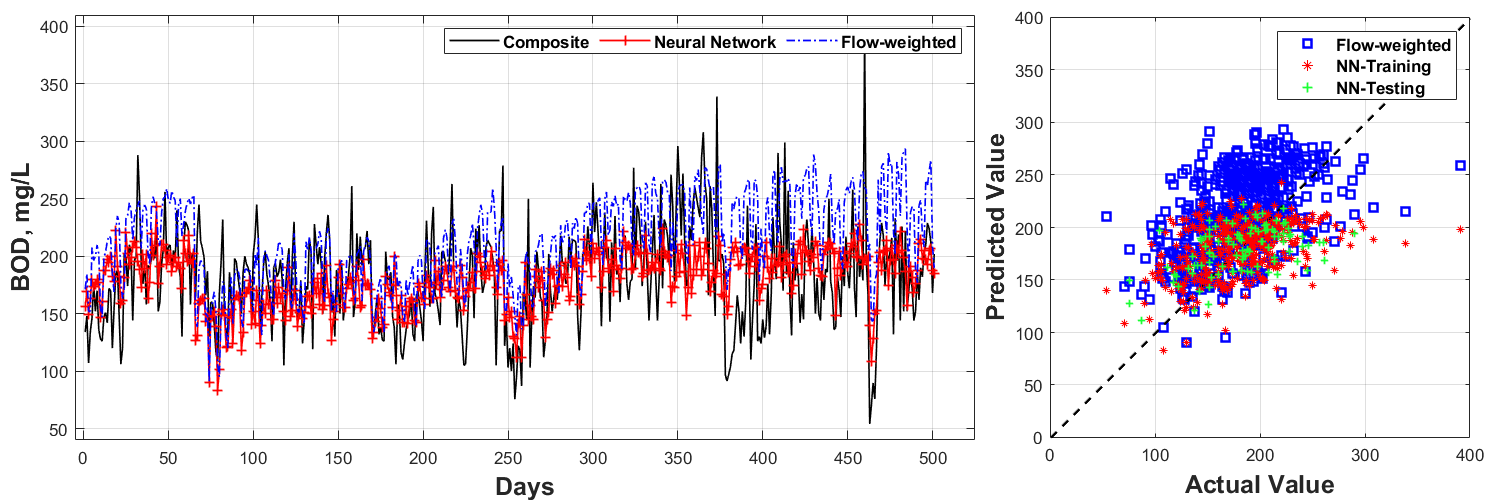

% Figrue to evaluate NN result 
fig = figure('position',[0.1 0.1 1200 400],'Units','centimeters');
ax1 = axes('position',[0.05,0.12,0.6,0.85]);
L1 = plot(yBOD(~labels_matrix(:,3),:),'-','color','k','LineWidth',1);
hold on; 
L2 = plot(predict(net,data_cube(:,:,:,~labels_matrix(:,3))),'-+','color','r','LineWidth',1);
L3 = plot(y_hat(~labels_matrix(:,3)),'-.','color','b','LineWidth',1);

   % Legend Setting
    % extract the handles that require legend entries
    hleglines = [L1 L2 L3];
    legend(hleglines,'Composite','Neural Network','Flow-weighted','FontSize',10,'FontWeight','bold',...
        'NumColumns',3);
    
    % X&Y ticks
    ylim([40,410]);
    xlim([-5,525]);
    
    % X & Y labels
    xlabel('Days','FontSize',15,'FontWeight','bold');
    ylabel('BOD, mg/L','FontSize',15,'FontWeight','bold');
    grid on;
    hold off;
    
    ax2 = axes('position',[0.7,0.12,0.28,0.85]);
    actual = yBOD(~labels_matrix(:,3)); % Only use the clean labeled data
    pred= y_hat(~labels_matrix(:,3));
    
    p1=scatter(actual,pred,'Marker','square','MarkerEdgeColor','blue','LineWidth',1.5);
    hold on;
    plot(1*0:max([actual;pred])+10,'--k','LineWidth',1.5);
    hold off;
    set(gca,'plotboxaspectratio',[1 1 1]);
    box on;
    grid on;
    xlabel('Actual Value','FontSize',15,'FontWeight','bold');
    ylabel('Predicted Value','FontSize',15,'FontWeight','bold');
    
    hold on;
    p2 = scatter(YTrain,YTrain_nnpred ,'*r','SizeData',20,'LineWidth',0.5);
    hold on;
    p3 = scatter(YTest,Ytest_nnpred,'+','SizeData',20,'LineWidth',1,'MarkerEdgeColor',[0.1 1 0.2]);
    xlim([0 400]);
    ylim([0 400]);
    
    % extract the handles that require legend entries
    hleglines = [p1(1) p2 p3];
    legend(hleglines,'Flow-weighted','NN-Training','NN-Testing',...
        'FontSize',10,'FontWeight','bold');
    saveas(gcf,'.\\figures\\CombinedNNEvaluation.png');

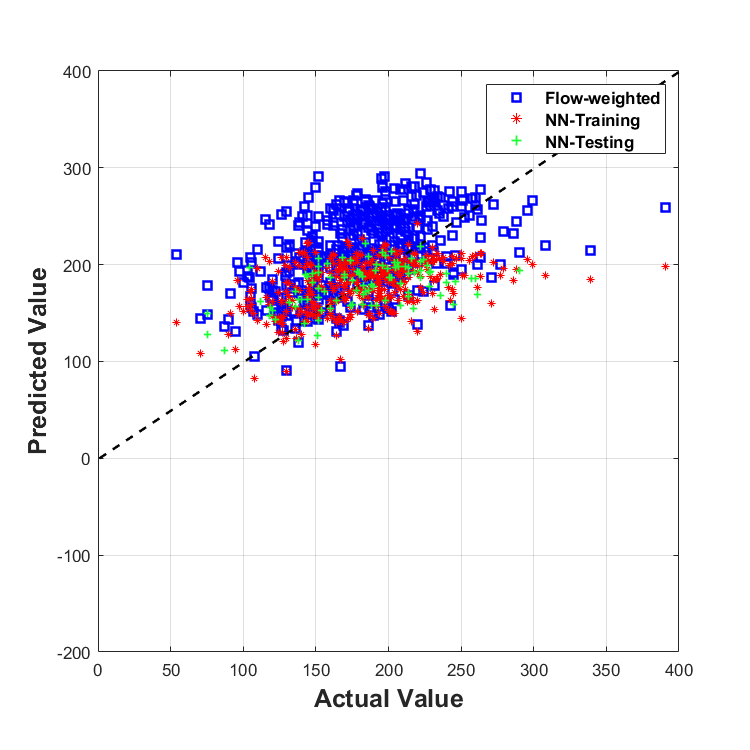

% plot the result
figure('position',[100 100 600 600]);
set(gca,'FontSize',18)
actual = yBOD(~labels_matrix(:,3)); % Only use the clean labeled data
    pred= y_hat(~labels_matrix(:,3));
    
    p1=scatter(actual,pred,'Marker','square','MarkerEdgeColor','blue','LineWidth',1.5);
    hold on;
    plot(1*0:max([actual;pred])+10,'--k','LineWidth',1.5);
    hold off;
    set(gca,'plotboxaspectratio',[1 1 1]);
    box on;
    grid on;
    xlabel('Actual Value','FontSize',15,'FontWeight','bold');
    ylabel('Predicted Value','FontSize',15,'FontWeight','bold');
    
    hold on;
    p2 = scatter(YTrain,YTrain_nnpred ,'*r','SizeData',20,'LineWidth',0.5);
    hold on;
    p3 = scatter(YTest,Ytest_nnpred,'+','SizeData',20,'LineWidth',1,'MarkerEdgeColor',[0.1 1 0.2]);
    xlim([0 400]);
    ylim([-200 400]);
    
    % extract the handles that require legend entries
    hleglines = [p1(1) p2 p3];
    legend(hleglines,'Flow-weighted','NN-Training','NN-Testing',...
        'FontSize',10,'FontWeight','bold') %,'location','northoutside','numcolumns',3);

% Calcualte how many points are within 1 std of actual measurements     
sum(abs([YTrain; YTest]-[YTrain_nnpred; Ytest_nnpred])<=43)/501

ans = 0.7545

sum(abs([YTrain; YTest]-[YTrain_nnpred; Ytest_nnpred])<=43*2)/501

ans = 0.9681

% Calcualte how many points are within 1 std of actual measurements   - flow
% weighted 
sum(abs(actual-pred)<=43)/501

ans = 0.5529

sum(abs(abs(actual-pred))<=43*2)/501

ans = 0.9102

% Figrue to validate dirty data not fitting quite well in the NN network model  
XDirty  = data_cube(:,:,:,dirty_id); % only subset the clean data for training 
YDirty  = yBOD(dirty_id);
YDirty_pred = predict(net, XDirty);

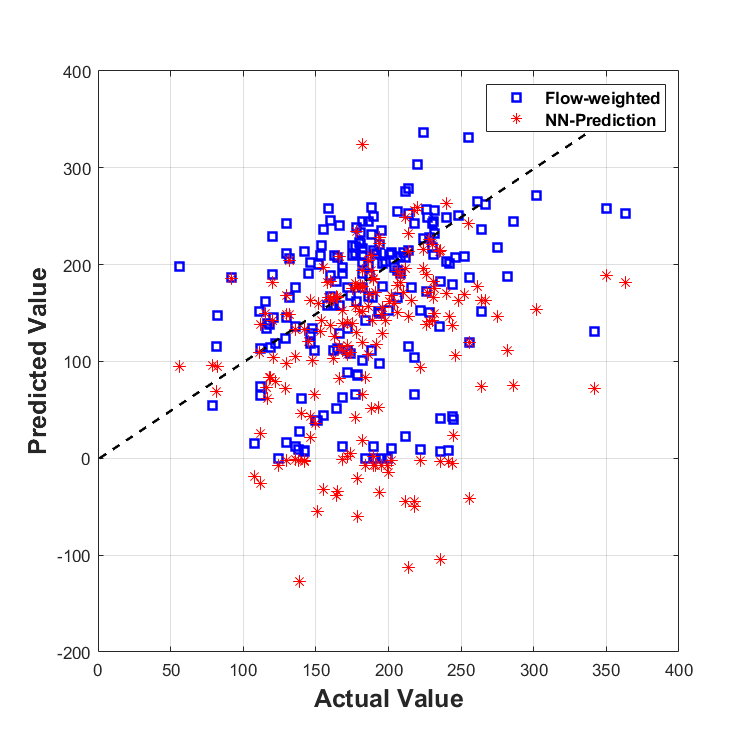


% plot the result
figure('position',[100 100 600 600]);
set(gca,'FontSize',18)
actual = yBOD(labels_matrix(:,3)); % Only use the dirty labeled data 
pred= y_hat(labels_matrix(:,3));   

ax1=scatter(actual,pred,'Marker','square','MarkerEdgeColor','blue','LineWidth',1.5);
hold on; 
plot(1*0:max([actual;pred])+10,'--k','LineWidth',1.5);
hold off;
set(gca,'plotboxaspectratio',[1 1 1]);
box on;
grid on;
xlabel('Actual Value','FontSize',15,'FontWeight','bold');
ylabel('Predicted Value','FontSize',15,'FontWeight','bold');

hold on;
ax2 = scatter(YDirty,YDirty_pred ,'*r','SizeData',50,'LineWidth',0.5);

% extract the handles that require legend entries
hleglines = [ax1 ax2 ];
legend(hleglines,'Flow-weighted','NN-Prediction',...
    'FontSize',10,'FontWeight','bold');

disp(['RMSE for Flow-weighted prediction : ', num2str(sqrt(mean((yBOD(~labels_matrix(:,3)) - y_hat(~labels_matrix(:,3))).^2)))]);

RMSE for Flow-weighted prediction : 52.1422


disp(['RMSE for NN prediction : ', num2str(sqrt(mean(([YTrain; YTest] - [YTrain_nnpred;Ytest_nnpred]).^2)))]);

RMSE for NN prediction : 39.1257


disp(['STD for actual value: ', num2str(std(yBOD(~labels_matrix(:,3))))]);

STD for actual value: 42.9136


clear actual ans ax1 ax2 ax3 cm data_cube fig hleglines i idx L1 L2 L3 miniBatchSize options p1 p2 p3 pred X xflow_mean Y ;

disp(['Min for actual value: ', num2str(min(yBOD(~labels_matrix(:,3))))]);

Min for actual value: 54


disp(['Max for actual value: ', num2str(max(yBOD(~labels_matrix(:,3))))]);

Max for actual value: 391


disp(['Mean for actual value: ', num2str(mean(yBOD(~labels_matrix(:,3))))]);

Mean for actual value: 181.5747


% Save current results into a cache workspace
save workspace_cache;

% load a cache workspace
clear;
load workspace_cache;